cov test

s1 = z1(:, 1);
s2 = z1(:, 4);

l = 1:size(s1,1);
ls = size(s1,1);
gccphat(s2, s1)

ans = 0

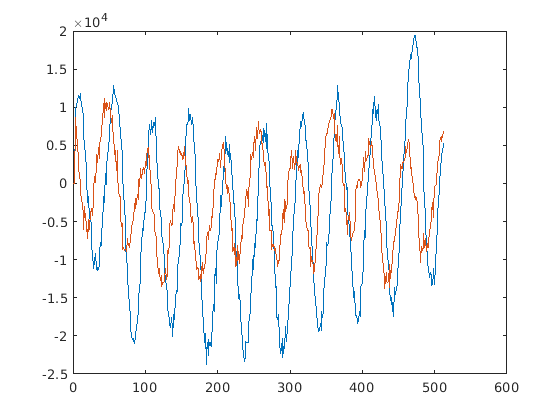

plot(l,s2,l,s1)

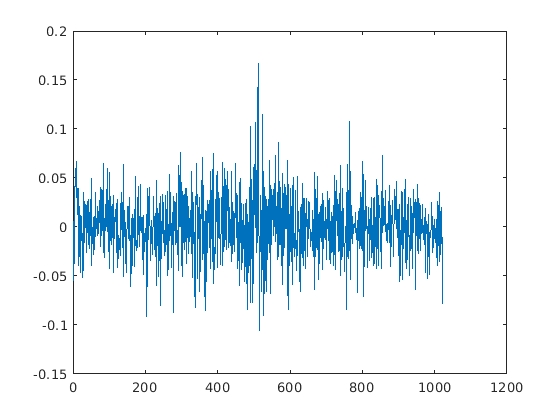

[gccp, r12] = gccphat(s1,s2);
plot(real(r12))

gccp

gccp = 0

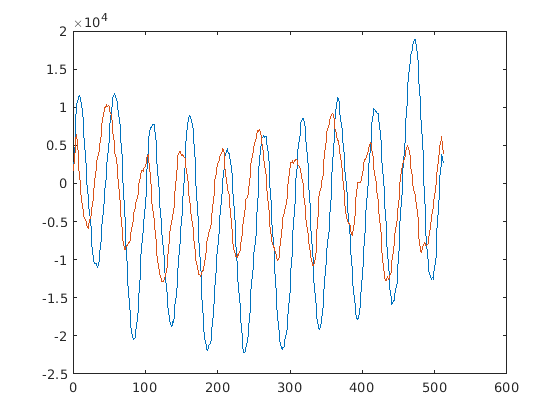


cs1 = conv(s1, ones(5,1)*0.2, 'same');
cs2 = conv(s2, ones(5,1)*0.2, 'same');
plot(l,cs2,l,cs1)

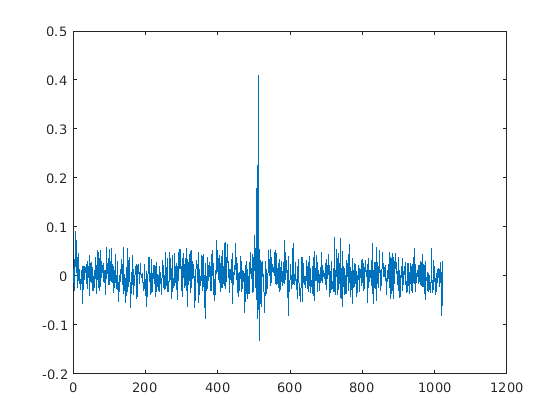

[gccp, r12] = gccphat(cs1,cs2);
plot(real(r12))

gccp

gccp = 0

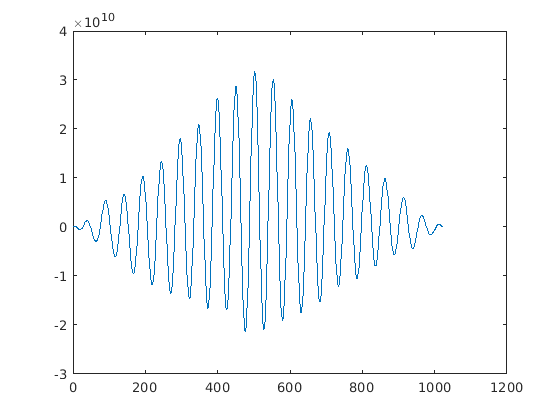

a = [];
for j=1:size(s1,1)*2
    tmp = sum([zeros(ls,1); s1; zeros(ls,1)] .* [zeros(j,1); s2; zeros(ls*2-j,1)]);
    a(j) = tmp;
end

plot(a)

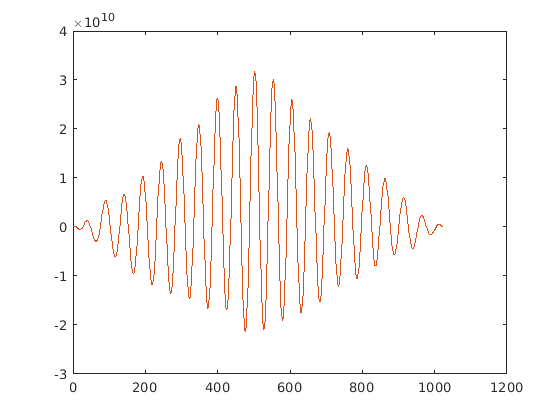

b = [conv(s1, s2(end:-1:1));0];
plot(1:ls*2, a, 1:ls*2, b)

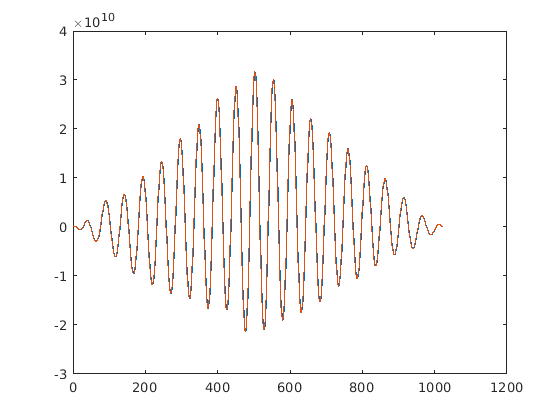

fs1e = fft([s1; zeros(ls,1)]);
fs2e = fft([zeros(ls,1); s2]);
fs12e = fs1e.*conj(fs2e);
ce = ifft(fs12e);
plot(1:ls*2,ce, 1:ls*2, b)

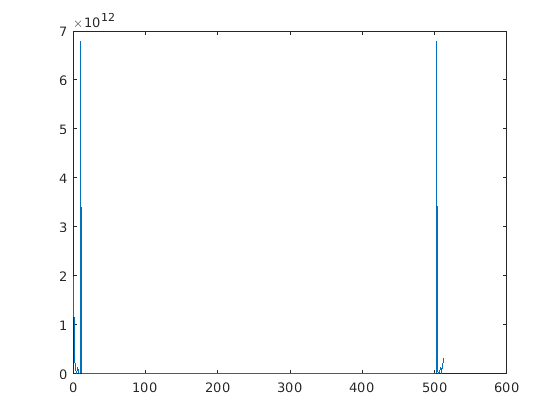


fs1 = fft(s1);
fs2 = fft(s2);
fs12 = fs1.*conj(fs2);
plot(abs(fs12))

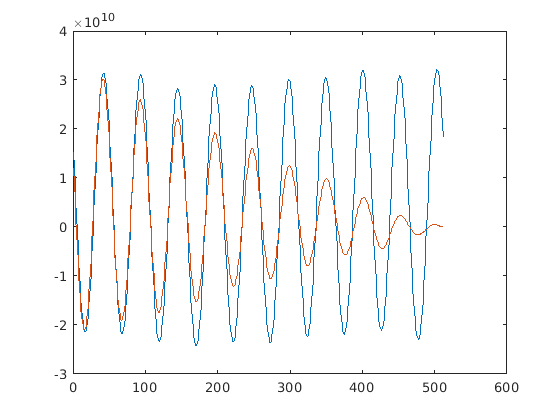

c = ifft(fs12);
d = ifft(fs12./abs(fs12));
plot(1:ls,c, 1:ls, b(ls+1:end))

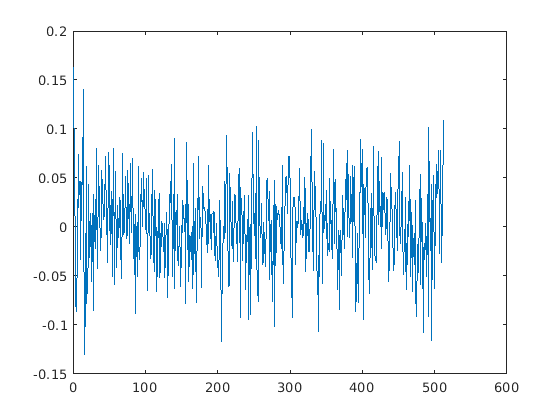

plot(d)